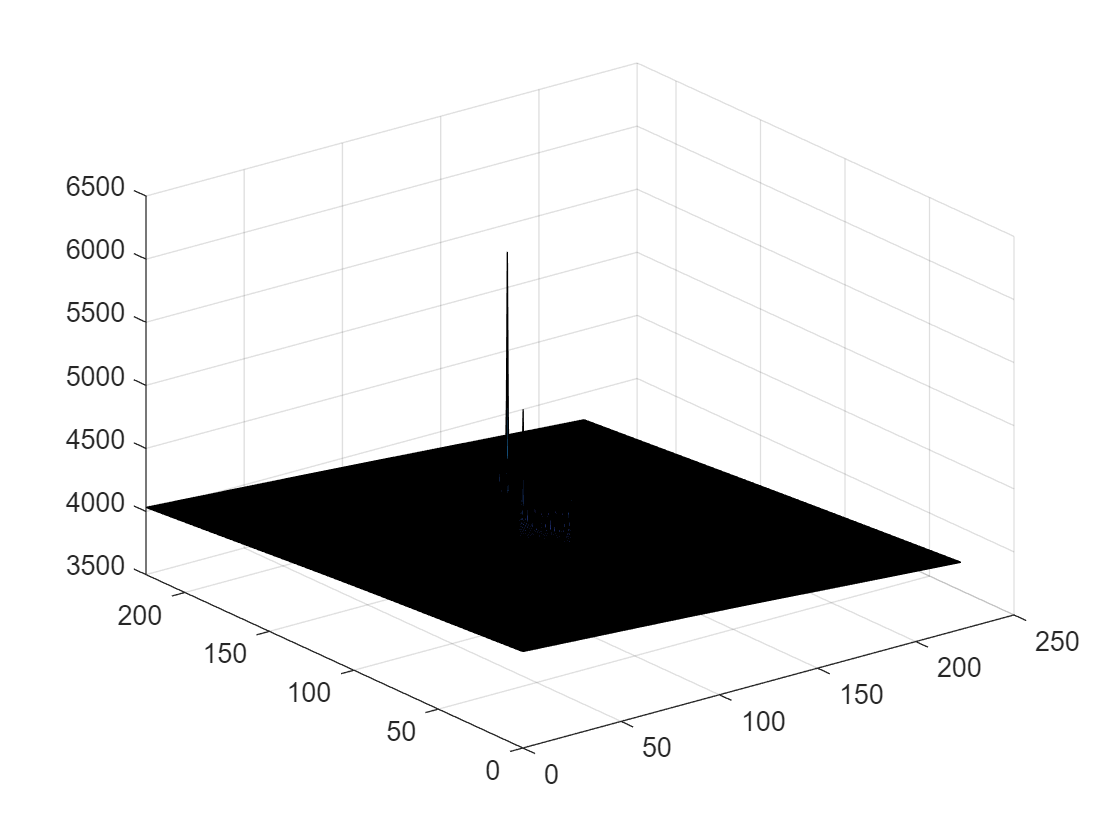

clear all
clf 
%% 定义函数输入
r=7;%最小转弯半径
Stepsize=0.01;%路径的生成间隔

sure=3;%保证安全的预留距离
% R=10+sure;


mapsize=200;
draw_map=2000;
num=0;%%%%随机障碍物数量
R=[20,20];%%%障碍物半径范围;
num_obs_nocircle=5;
num_steps=100;%%%%边界上几个点
% Start_Point = [100,0,-pi/6];
% End_Point = [200,200,-pi/2];%[x,y,角度]

% Start_Point = [round(rand(1,2)*mapsize),-pi+rand(1)*2*pi];
% End_Point = [round(rand(1,2)*mapsize),-pi+rand(1)*2*pi];%[x,y,角度]

Start_Point = [0,0,-pi+rand(1)*2*pi];
Start_Point = [0,0,-pi];
End_Point = [2000,2000,-pi+rand(1)*2*pi];%[x,y,角度]



outline_all=[];
center=[   
100,100
         ];

for i=1:length(center(:,1))
    [outline,vertex,expandedPolygon]=obtain_obs_nocircle_hand(center(i,:)',mapsize,R,num_steps,Start_Point,End_Point,sure);
    if ~isempty(outline)
        outline=[outline,ones(length(outline(:,1)),1)*i];
        outline_all=[outline_all;outline];
        obs_no_circle{i}=expandedPolygon;
        obs_no_circle_in{i}=vertex;
    end
end









% [outline_all,obs_no_circle,obs_no_circle_in]=obtain_obs_no_circle_all(num_obs_nocircle,mapsize,R,num_steps,Start_Point,End_Point,sure);

% total_field=obtian_field(mapsize+R(2)+sure,End_Point,outline_all,k_att,k_rep,r_search);
[obs,obs_no_circle,obs_no_circle_in,outline_all]=obtain_map(num,mapsize,Start_Point, End_Point,R,r,obs_no_circle,obs_no_circle_in,outline_all);%[x,y,障碍物的安全半径R]


r_search=15;%%探测半径
k_att=1.5;%计算引力需要的增益系数
k_rep=30;%计算斥力的增益系数，都是自己设定的。


% load("drawfinal.mat") 
total_field=obtian_field(mapsize+R(2)+sure,End_Point,outline_all,k_att,k_rep,r_search);

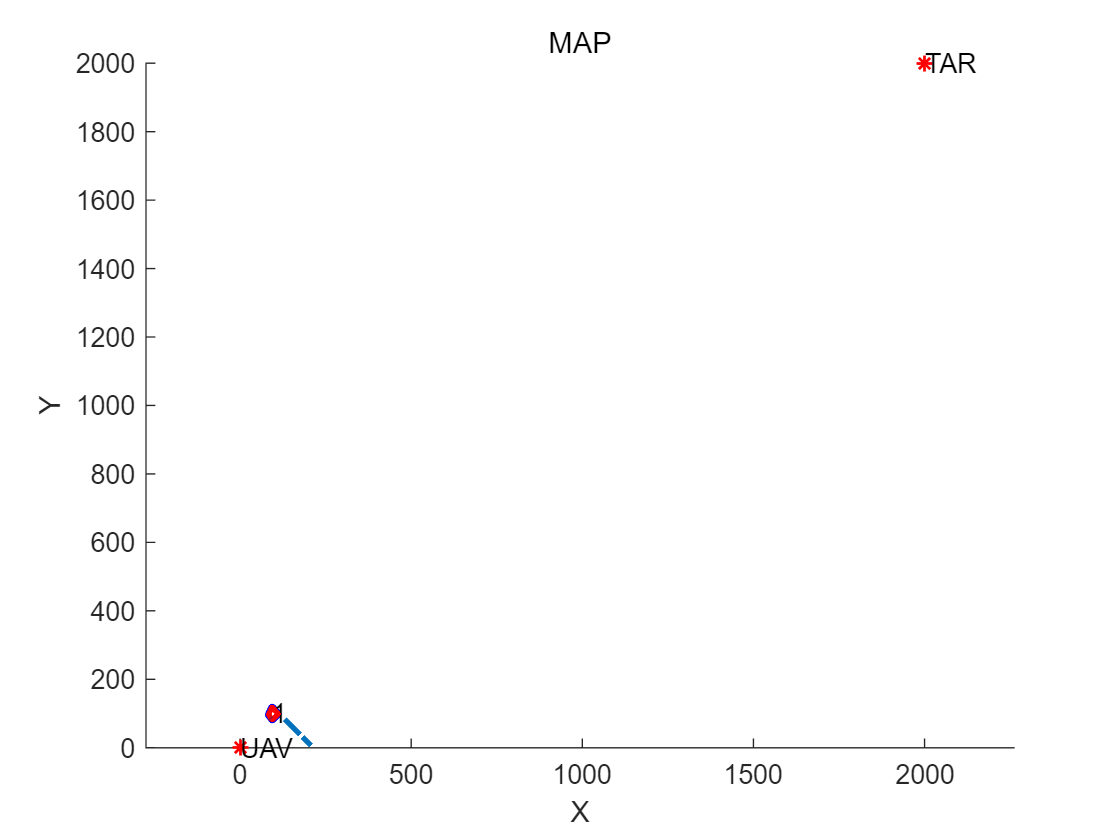

Draw_map(Start_Point,End_Point,obs,sure,obs_no_circle,obs_no_circle_in);%绘制地图
k=(End_Point(2)-Start_Point(2))/(End_Point(1)-Start_Point(1));
k=-1/k;
draw_line(k,91.8445,83.262,87,91.8445)
draw_line(k,130.1644,83.3416,130.164,213)


tic
[final_path,open,close]=A_dubins_nocircle(Start_Point,End_Point,obs,sure,r,obs_no_circle,outline_all,Stepsize,total_field);

from           -1                  avoid  1
1
1.1
directly find 1-2 safe
1.2
directly find 1-2 safe
Find Goal!!
历时 1.660958 秒。
运行时间: 1.6633


toc

历时 1.671771 秒。


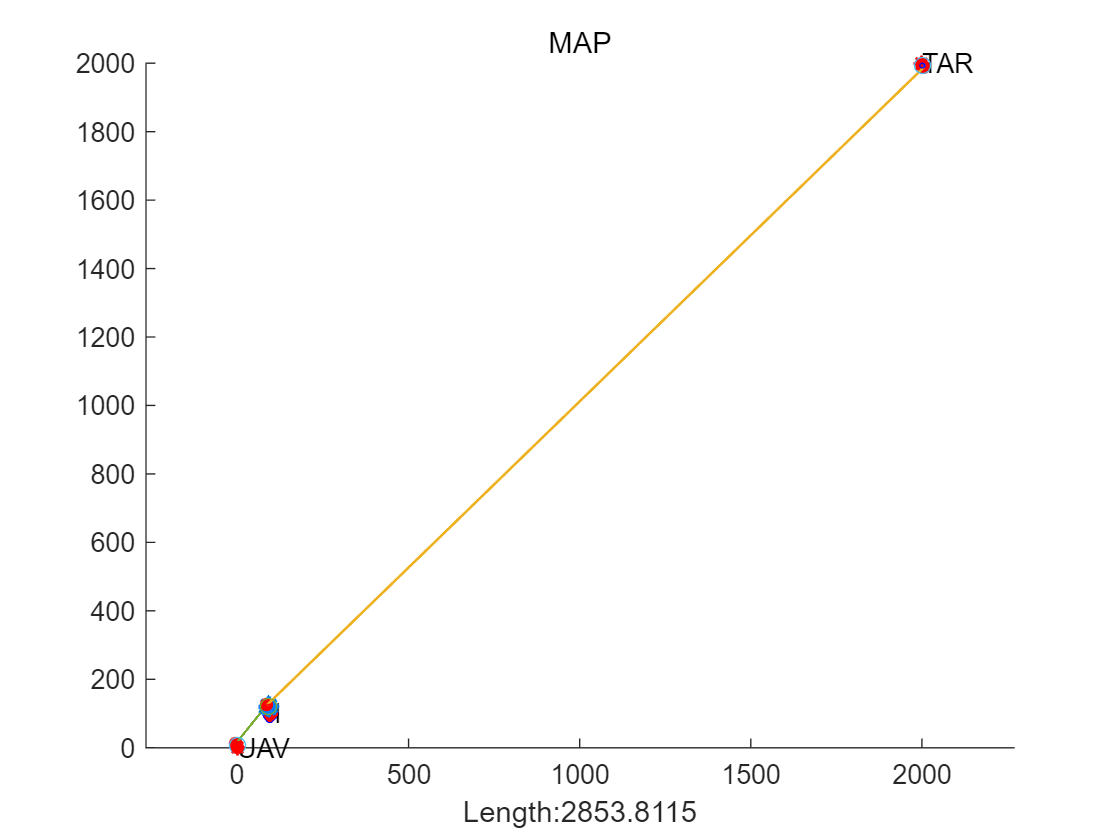

figure
Draw_map(Start_Point,End_Point,obs,sure,obs_no_circle,obs_no_circle_in);%绘制地图
Draw_pathA_no_circle(final_path);

hold off

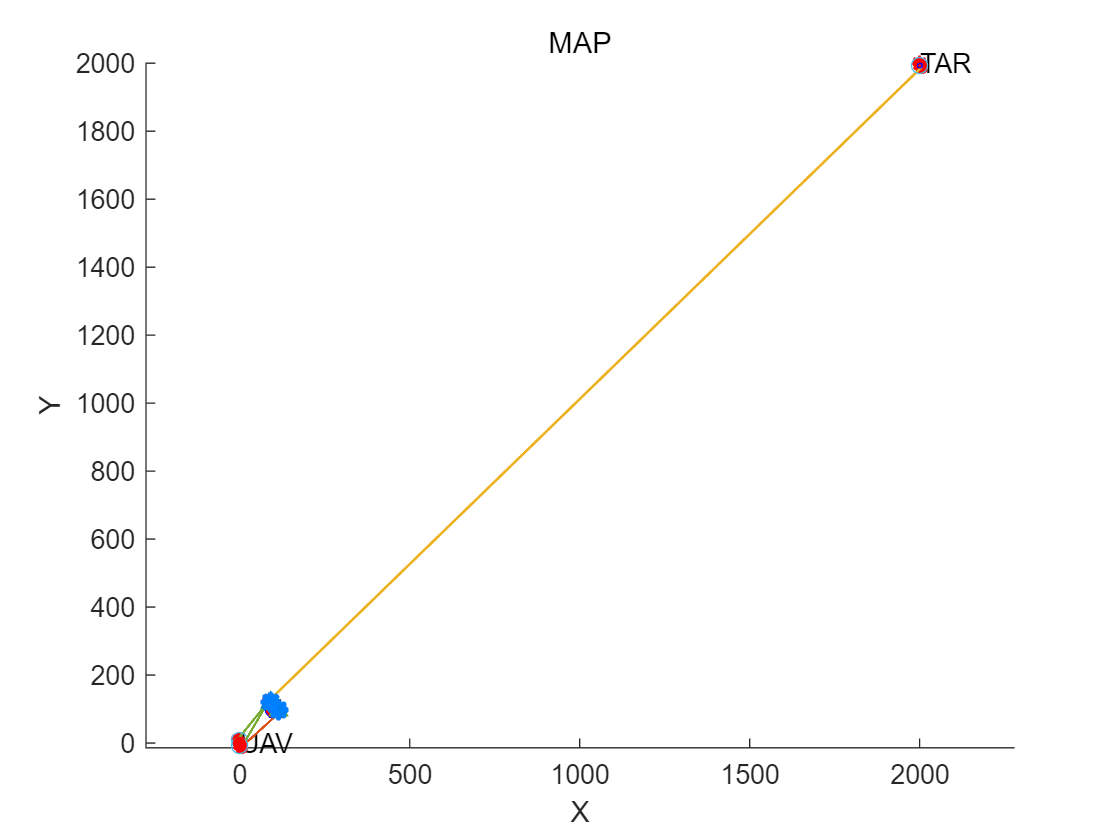

figure

Draw_map(Start_Point,End_Point,obs,sure,obs_no_circle,obs_no_circle_in);%绘制地图
Draw_pathA_no_circle(close);                    
Draw_pathA_no_circle_open_close(open);
draw_line(1,0,0,0,0)
hold off


[draw_path,vtheta_all]=obtain_vtheta_drawpath_nocircle(final_path);


